# Demonstration of the Puig and Siebenbrunner (2018) Algorithm

Start by initializing a simple system of three nodes:

vecE = [0;50;10];
matL = [0 20 10;5 0 24;10 0 0];
matL(:,:,2) = [0 0 15;15 0 24;10 0 0];
matTheta = [0 0.1 0;0 0 0.15;0 0 0];
numK = 1;

The equity has to be computed iteratively, we can get a first approximation, seeing that the first node is already in default, and the second very close to being in default: 

vecEquity_approx = vecE + sum(sum(matL,3),1)' - sum(sum(matL,3),2);
vecEquity_approx = vecEquity_approx + max(0,matTheta'*vecEquity_approx);
disp([{'Approximated Equity' 'Defaulted'};
    num2cell([vecEquity_approx vecEquity_approx < 0])])

    'Approximated Equity'    'Defaulted'
    [                 -5]    [        1]
    [                  2]    [        0]
    [            63.3000]    [        0]



## Bail-In

For bail-ins, we need to set the threshold that triggers a bail-in, as well as a target capitalization level.

vecLambdaB = zeros(length(vecE),1) + 0.05;
vecLambdaR = zeros(length(vecE),1) + 0.2;

We will look at two different kinds of conversion, one with a full writedown for bailed in creditors, another one with a so-called 'fair' conversion, which ensures that no wealth is transferred between bailed in creditors and/or old equity owners.

dblGamma = 0.5;
funConversionWriteDown = @(x,y,z) zeros(size(x,1), size(x,1), size(x,2));
funConversionFair = fairConversionFun(dblGamma);
[matP_WriteDown,vecEquity_WriteDown,matTheta_WriteDown,matL_WriteDown,~,...
    vecBailedInBanks_WriteDown] = calcPaymentsBailIn...
    (vecE,matL,matTheta,numK,funConversionWriteDown,vecLambdaB,vecLambdaR);
vecLambdaWriteDown = vecEquity_WriteDown ./ (vecEquity_WriteDown + ...
    sum(sum(matL_WriteDown,3),2));

[matP_FairConversion,vecEquity_FairConversion,matTheta_FairConversion,...
    matL_FairConversion,~,vecBailedIn_FairConversion] = calcPaymentsBailIn...
    (vecE,matL,matTheta,numK,funConversionFair,vecLambdaB,vecLambdaR);
vecLambdaFairConversion = vecEquity_FairConversion ...
    ./ (vecEquity_FairConversion + sum(sum(matL_FairConversion,3),2));

We see that the bailed in banks manage to reach their capitalization levels under a fair conversion, but the first one fails to do so under a full writedown:

disp([{'Capitalization after fair bail-in' ...

    'Capitalization after fair bail-in'    'Capitalization after bail-in with writedown'
    [                           0.2000]    [                                     0.0957]
    [                           0.2006]    [                                     0.2038]
    [                           0.7290]    [                                     0.6910]



    'Capitalization after bail-in with writedown'}; ...
    num2cell([vecLambdaFairConversion vecLambdaWriteDown])])
disp([{'Equity after fair bail-in' ...

    'Equity after fair bail-in'    'Equity after bail-in with writedown'
    [                   8.0000]    [                             3.3846]
    [                  14.0484]    [                            14.3385]
    [                  53.7923]    [                            44.7154]



    'Equity after bail-in with writedown'}; ...
    num2cell([vecEquity_FairConversion vecEquity_WriteDown])])

We also see that the matrix of interbank holdings is changed as a result of the bail-in with fair conversion (there are no changes in the holdings following a writedown because the bailed in creditors do not gain equity shares):

matTheta_FairConversion

matTheta_FairConversion =          0    0.0143    0.5000
    0.3297         0    0.6775
         0         0         0


matTheta_WriteDown

matTheta_WriteDown =          0    0.1000         0
         0         0    0.1500
         0         0         0


## Contingent convertible debt

In the case of CoCo debt, we assume that the fraction of bail-in shares is set in the contracts. Here we assume a full writedown. We further have to set a trigger threshold for when a conversion is triggered, as well as a fraction of the liabilities in the affected asset class that will be bailed in.

matConversion = zeros(3);
vecLambdaC = zeros(3,1) + 0.05;
vecF = [0.5;0.5;0.5];

We that the total equity in the system is even slightly lower than in the case of a bail-in with a full writedown.

[matP,vecEquity_CoCo] = calcPaymentsCoCos(vecE,matL,matTheta,numK,matConversion,...
    vecLambdaC,vecF);
vecEquity_CoCo

vecEquity_CoCo =     7.5000
    7.2500
   46.9750


## Valuation

We can also simulate payoffs under stochastic paths for external assets. 

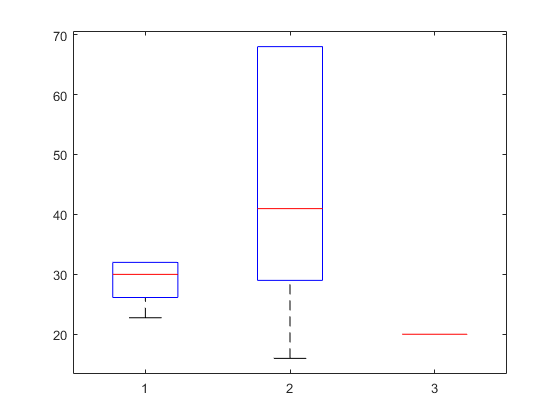

vecMu = [0.5;0.1;0.1];
matCovariance = [1 0 0;0 1 0;0 0 1];
numSimulations = 1000;
matValuationsFairBailIn = calcValuationsBailIn(vecE,vecMu,matCovariance,...
    matL,matTheta,numK,funConversionFair,vecLambdaB,vecLambdaR,numSimulations);
matValuationsCoCos = calcValuationsCoCos(vecE,vecMu,matCovariance,matL,...
    matTheta,numK,matConversion,vecLambdaC,vecF,numSimulations);
boxplot(squeeze(sum(matValuationsFairBailIn,2))')

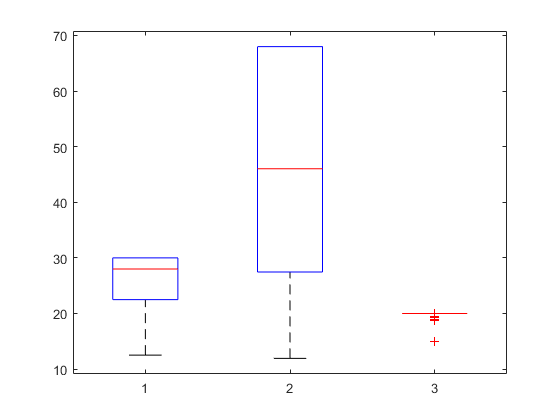

boxplot(squeeze(sum(matValuationsCoCos,2))')